# 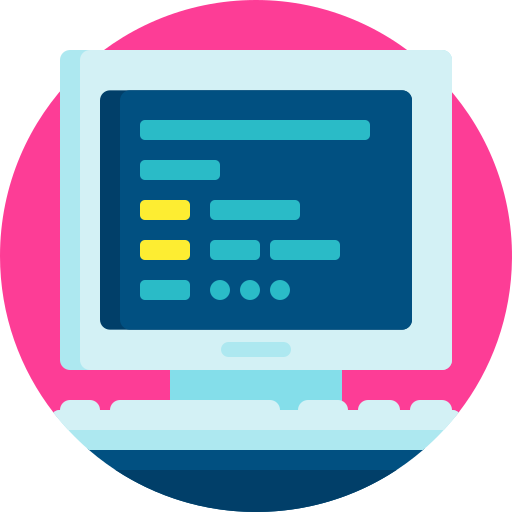

# Virtual Lab 6 - Inverse kinematics of a 2R robot arm

#### This Virtual Lab covers Section 5.4-5.5 of the notes.

- This Virtual Lab will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive (or on your PC if you are working on a laptop). 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on right`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (Windows) or CMD+ENTER (macOS).

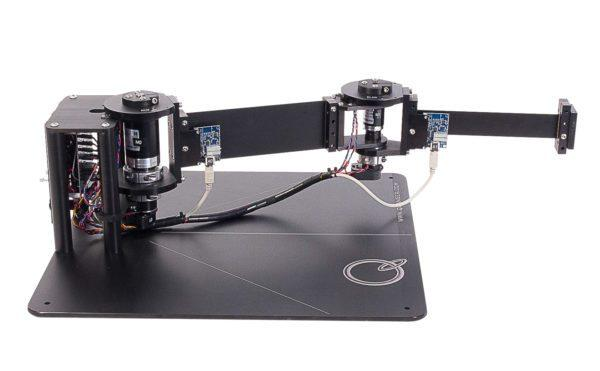

*2R planar manipulator from Quanser.*

This Virtual Lab will expand on the work done in **Virtual Lab 5** by exploring the concept of inverse kinematics for a planar 2R robot arm. You should make use of your developed **Virtual Lab 5** code where necessary.

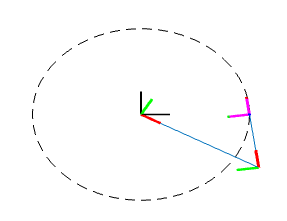

*Figure 1: 2R robot arm visualisation with end-effector following circular path in frame {W}.*

This Virtual Lab will require you to submit short video demos of your animations at certain points (**Question 5**, **Question 7 **and **Question 10**). While you are welcome to use screen recording software to capture the (short!) animation, a potentially easier method is to use MATLAB functionality to compile a .gif file. The process is detailed below:

Given a loop that is used in conjunction with *drawnow *to visualise an animation (e.g. plotting a sine wave with a frequency of $f=1$Hz, over one second), we can use the following code to create a gif of the animation.

clear

currentFolder = pwd;    %get the current working directory. You can see/set the current working directory in the address bar near the top of the interface.
filename = [pwd,'/','example_vid.gif'];  %this will append '/exampl_vid.gif' onto the working directory. The gif will be made in the current folder you are working in.

f = 1;
dT = 1/30;

figure(1),clf
xlim( [0 1]), ylim([-1,1])

hold on
for i=1:1/dT
    t=dT*i;
    y = sin(2*pi*f*t);
    plot(t,y,'rx')
    
    drawnow
    
    frame = getframe(gcf);   %gets the current frame from the figure.
    im = frame2im(frame);   %converts the frame to an image
    [imind,cm] = rgb2ind(im,256);
    if i == 1
        imwrite(imind,cm,filename,'gif', 'Loopcount',inf,'DelayTime',dT);   %sets the gif to loop continuously and also have an effective framerate of 1/dT
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append','DelayTime',dT);  %subsequent images are appended to the same file.
    end
    
    pause(dT);
end

The lines that we have added for making the gif are:

Note that you may want/need to change the gif filename and dT value. If you have set everything up correctly, you should find the .gif file in the designated file location. You can use this method in **Question 5, Question 7**, and **Question 10 ** to record gifs if you so desire. Just make sure to change the filename so that you do not overwrite previous gifs!

Using your knowledge and work from **Virtual Lab 5**, set up a 2R robot arm with link lengths of $l_1=0.5$m, and $l_2=0.25$m. The home positions of the two joints should be set to $0^\circ$, and the robot must operate solely in the ${\hat{\bf x}_W$-${\hat{\bf y}_W$ plane. Use the same naming conventions from **Virtual Lab 5**, e.g. `manipulatorBase` and `elbowJoint` .

%Add robot setup code here


Check that the 3D visualisation matches your understanding of the robot configuration.

%Add code here


*Hint: remember to use* `view(2) `*to view the 2D plane from the perspective of the z-axis.*

####  Question 1: Describe the workspace of the end-effector position.

%Answer block (if required)


We will again use ${\bf q}=[q_1 ~ q_2]^T$ to define our robot configuration, where $q_1$ contains the angle of the first joint (`baseJoint) `and $q_2$ contains the angle of the second joint (elbowJoint) . Set the joint positions of *q* such that the pose of the end-effector is ${^W\bf\xi}=[0.5~0.25~\frac{\pi}{2}]^T$. Confirm your mathematical understanding by visualising the robot configuration.

%Add code here


####  Question 2: What value of $\bf q$ is required to achieve the pose above?

%Answer block (if required)


If we were to specify some arbitrary end-effector pose within the workspace, it would be difficult to determine the joint angles required to achieve it without resorting to onerous trial and error using the forward kinematics. Fortunately inverse kinematics solves this problem for us. Our goal will be to specify the end-effector position in $\{W\}$ and then solve for the corresponding joint angles.

Our end-effector position is defined as 

$\pmatrix{p_x \cr p_y}=\pmatrix{l_1 \cos{\alpha}+l_2cos{(\alpha+\beta)} \cr 
l_1 \sin{\alpha}+l_2sin{(\alpha+\beta)}}$.

We have already explored other approaches, such as determining a closed-form solution using trigonometry. For this virtual lab we will use `MATLAB`'s [`solve`](https://in.mathworks.com/help/symbolic/sym.solve.html) function to find a closed-form algebraic solution for $\alpha$ and $\beta$:

syms px py a b real
syms l1 l2 positive

[a,b] = solve( px==l1*cos(a)+l2*cos(a+b),py==l1*sin(a)+l2*sin(a+b),a,b);
a = simplify( expand(a) )   %dont overwrite a and b variables, as they will be used later on.
b = simplify( expand(b) )

Even after simplification, the equations for $\alpha$ and $\beta$ are somewhat involved, but we just need to evaluate the algebraic solution using the given robot parameters and desired position. We will begin by setting our desired end-effector position as $^W{\bf p}^*=[0.5~0.25]^T$ and then solve for numerical $\alpha$ and $\beta$:

l1 = 0.5;   %length of link1
l2 = 0.25;  %length of link2
px = 0.5;
py = 0.25;

a_ = eval(a)    %evaluates the symbolic equation of a from the previous code block, using the specified parameters above
b_ = eval(b)

We end up with two paired solutions for $(\alpha,\beta)$, which implies that the end-effector can achieve the defined position with two different orientations. Note that variables *a *and *b* hold the *algebraic* solution, whereas *a_ *and *b_ *hold the *numerical* solution for the particular desired position and link lengths. 

Confirm that both solutions are valid by assigning the paired solutions (e.g. *a_(1) *and b_(1)) to the joint angles of *q* and then showing the corresponding robot configurations. You can show two different robot configurations on the same figure using *hold on *in between the two *show() *function calls.

%Add code here


####  Question 3: What are the two allowable orientations of the end-effectors for the desired position?

We now have a routine to position our end-effector in the task space, and we also have some choice about how we want the end-effector oriented. However, we do need to be mindful of our end-effector workspace. Use the closed-form solution to find the joint angles required to position the end-effector at the frame {W} origin.

px = 0;
py = 0;
a_ = eval(a)
b_ = eval(b)

The resulting required joint angles are complex numbers and this implies that the end-effector cannot reach this setpoint — it is outside the end-effector workspace (you may have noted the MATLAB warning stating that the *solve* solution was conditional). This should not be surprising based on $l_1>l_2$.

Lets try something more interesting. Generate a linearly spaced circular trajectory in frame {W}, within the robot workspace, with a radius of $r=0.4$m, and a centre at the origin of frame {W}. Using this generated trajectory, find the corresponding joint angles, and simulate the end-effector tracking the trajectory for one full rotation. Plot the trajectory as a black dotted line. 

%Add code here


####  Question 4: Copy/paste your code from above into the answer field in Amathuba.

####  Question 5: Provide a short demo video (using code to generate a gif, or a screen recording) of the end-effector tracking the circular trajectory. 

Generate a shortest-distance square-shaped trajectory, centred on the world-frame origin, that adheres to the end-effector workspace. Using this trajectory, find the corresponding joint angles and simulate the robot end-effector tracking this trajectory.

%Add code here


####  Question 6: Copy/paste your code from above into the answer field in Amathuba.

####  Question 7: Provide a short demo video (using code to generate a gif, or a screen recording) of the end-effector tracking the square trajectory. 

####  Question 8: What is the area of the largest square-shaped trajectory that can be achieved within our robot workspace?

Verify your answer below.

%Add code here


Having a closed-form solution for the desired joint angles is clearly quite appealing, but the algebraic relationship can become quite overwhelming when there are a large amount of joints. An alternate approach that can be generalised to any number of joints is using numerical optimisation. Given a desired pose, $^W{\bf \xi}^*$, an optimisation routine can attempt to minimise the difference between this desired pose and the actual pose that is made up of the forward kinematics, $\mathcal{K}({\bf q})$. Explicitly, we want to minimise the cost function $J=||\mathcal{K}({\bf q})-^W{\bf\xi}^*||$. For the 2D planar case, we will only use the position to populate the cost function, namely

$J=||\mathcal{K}({\bf q})_{t}-^W{\bf p}^*||$,

where $\mathcal{K}({\bf q})_{t}=[{^W{p_x} ~ {^W{p_y}]^T$ — the first two elements of the pose vector.

Using our original test point of $^W{\bf p}^*=[0.5~0.25]^T$, we will use `MATLAB`'s [`fminsearch`](https://www.mathworks.com/help/matlab/ref/fminsearch.html) function to minimise our cost function

px=0.5; py=0.25;    %desired x-y location of end-effector

q_guess = [0 0]' %initial guess of configuration.

options = optimset('fzero');    %sets the minimisation tolerance of e to "zero" — actually about 2.2e-16.
e = @(q_) ( l1*cos( q_(1) )+l2*cos( q_(1)+q_(2) )-px )^2 + ( l1*sin( q_(1) )+l2*sin( q_(1)+q_(2) )-py )^2;
q_opt = fminsearch( e, q_guess,options )

figure(1),clf
show(robot,q_opt)
view(2)

which returns the same result as before. Unlike the closed-form solution, this optimisation routine returns a single solution that depends on the initial guess of $\bf q$.

Play around with different initial guesses to see when the other valid configuration is found.

%Add code here


Adjust your code from **Question 6 **and **Question 7** to instead use the numerical optimisation routine above in order to track the same square-shaped trajectory. Ensure that the robot configurations used to follow the defined trajectory always uses the minimal amount of joint angle changes (no large sudden joint angle changes).

%Add code here


####  Question 9: Copy/paste your code from above into the answer field in Amathuba.

####  Question 10: Provide a short demo video (using code to generate a gif, or a screen recording) of the end-effector tracking the square trajectory. 

####  Question 11: Upload your completed Virtual Lab .mlx file in Amathuba. Make sure to include your student number in the file name.